Consider the following system with 2 dofs

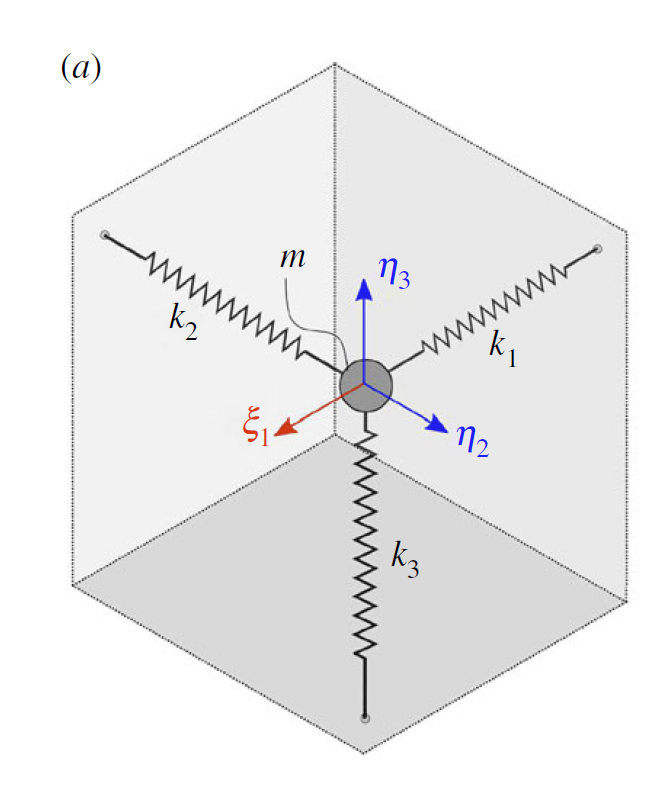reproduced from [1]

The equation of motion for the system is given by


$$\ddot{x}_1+2\zeta_1\omega_1\dot{x}_1+\omega_1^2x_1+\frac{\omega_1^2}{2}(3x_1^2+x_2^2 + x_3^2)+\omega_2^2x_1x_2+\omega_3^2x_1x_3+\frac{\omega_1^2+\omega_2^2 + \omega_3^2}{2}x_1(x_1^2+x_2^2+x_3^2)=\epsilon f_1\cos\Omega t,\\

\ddot{x}_2+2\zeta_2\omega_2\dot{x}_2+\omega_2^2x_2+\frac{\omega_2^2}{2}(3x_2^2+x_1^2 + x_3^2)+\omega_1^2x_1x_2+ \omega_3^2x_2 x_3 + \frac{\omega_1^2+\omega_2^2 + \omega_3^2}{2}x_2(x_1^2+x_2^2+ x_3^2)=0,\\
\ddot{x}_3+2\zeta_3\omega_3\dot{x}_3+\omega_3^2x_3+\frac{\omega_3^2}{2}(3x_3^2+x_1^2 + x_2^2)+\omega_1^2x_1x_3+ \omega_2^2x_2x_3 +\frac{\omega_1^2+\omega_2^2 + \omega_3^2}{2}x_3(x_1^2+x_2^2+ x_3^2)=0$$


[1] Buza, G., Jain, S., & Haller, G. (2021). Using spectral submanifolds for optimal mode selection in nonlinear model reduction. *Proceedings of the Royal Society A: Mathematical, Physical and Engineering Sciences*, *477*(2246), 20200725.

clear all

## Setup model

om1 = 2;
om2 = 3;
om3 = 5;
zeta1 = 0.01;
zeta2 = 0.05;
zeta3 = 0.05;
f1    = 1;
[B,A,Fnl,Fext] = build_model_none(om1,om2,om3,zeta1,zeta2,zeta3,f1,'none');

DSorder = 1;
DS = DynamicalSystem(DSorder);
set(DS,'B',B,'A',A,'F_non',Fnl);
set(DS.Options,'Emax',6,'Nmax',20,'Intrusion','none', 'notation','multiindex')

**Linear Modal analysis**

[V,D,W] = DS.linear_spectral_analysis();


 The first 6 nonzero eigenvalues are given as 
  -0.0200 + 1.9999i
  -0.0200 - 1.9999i
  -0.1500 + 2.9962i
  -0.1500 - 2.9962i
  -0.2500 + 4.9937i
  -0.2500 - 4.9937i



## Autonomous SSM 

S = SSM(DS);
set(S.Options, 'reltol', 1, 'notation', 'multiindex');
resonant_modes = [1 2]; % choose master spectral subspace
order = 13;                  % SSM expansion order
S.choose_E(resonant_modes)

(near) outer resonance detected for the following combination of master eigenvalues
     2     0
     2     1
     3     1
     3     2
     4     2
     4     3
     5     3
     5     4
     6     4
     0     2
     1     2
     1     3
     2     3
     2     4
     3     4
     3     5
     4     5
     4     6
     2     0
     3     0
     3     1
     4     1
     4     2
     5     2
     5     3
     6     3
     6     4
     0     2
     0     3
     1     3
     1     4
     2     4
     2     5
     3     5
     3     6
     4     6

These are in resonance with the follwing eigenvalues of the slave subspace
  -0.1500 + 2.9962i
  -0.1500 + 2.9962i
  -0.1500 + 2.9962i
  -0.1500 + 2.9962i
  -0.1500 + 2.9962i
  -0.1500 + 2.9962i
  -0.1500 + 2.9962i
  -0.1500 + 2.9962i
  -0.1500 + 2.9962i
  -0.1500 - 2.9962i
  -0.1500 - 2.9962i
  -0.1500 - 2.9962i
  -0.1500 - 2.9962i
  -0.1500 - 2.9962i
  -0.1500 - 2.9962i
  -0.1500 - 2.9962i
  -0.1500 - 2.9962i
  -0.1500 - 2.9962i
  -0.2500 + 

[W0,R0] = S.compute_whisker(order);

#### Reduced dynamics in symbolic form

lamdMaster = DS.spectrum.Lambda(resonant_modes);
options = struct();
options.isauto = true; 
options.isdamped = false;
options.numDigits = 4;
y = reduced_dynamics_symbolic(lamdMaster,R0,options)

Symbolic string to latex 

% sympref('FloatingPointOutput',true);
% rho1dot = latex(y(1))
% theta1dot = latex(y(2))

Convergence of backbone curve

% 3.467*rho_1^6 - 8.963*rho_1^4 + 0.8168*rho_1^2 + 2.0
syms rho_1 positive
[coeffs,powers]=coeffs(y(2));
tmp = simplify(log(powers));
exp_idx = double(tmp./log(rho_1));

rhosamp = 0:0.01:0.4;
orders = [3 5 7 9 11 13];
plot_backbone_curves(double(coeffs),exp_idx,rhosamp,orders)

#### visualization of 2D SSM

rhosamp = 0:0.01:0.35;
plotdofs = [1 5 6]; 
plot_2D_auto_SSM(W0,rhosamp,plotdofs,{'$x_1$','$\dot{x}_2$','$\dot{x}_3$'});
plotdofs = [1 2 5]; 
plot_2D_auto_SSM(W0,rhosamp,plotdofs,{'$x_1$','${x}_2$','$\dot{x}_2$'});
plotdofs = [1 4 5]; 
plot_2D_auto_SSM(W0,rhosamp,plotdofs,{'$x_1$','$\dot{x}_1$','$\dot{x}_2$'});
figssm = gcf;

#### Transient response validation

We take an initial condition on SSM and perform forward simulation using both the reduced-order model and the full model

tf = 50;
nsteps = 1000;
q0 = 0.35*exp(1i*0.5);
q0 = [q0;conj(q0)];
z0 = reduced_to_full_traj(0,q0,W0);
traj = transient_traj_on_auto_ssm(DS, resonant_modes, W0, R0, tf, nsteps, 1:6, [], q0);

Reference solution from forward simulation

[tInt1,zInt1] = time_integration_transient(DS,2*pi,...
    'nSteps', nsteps/tf, 'nCycles', tf, ...
    'integrationMethod','ode45','outdof',1:6,'init',z0);

% options = odeset('RelTol',1e-8,'AbsTol',1e-10);
% epf = 0; omega = 2*pi; 
% psp = [epf; omega];
% [tInt1, zInt1] = ode15s(@(t,x) spring_ode(t,x,psp,'none'), [0 tf], z0(1:6),options); % Transients

figure;
plot(traj.time,traj.phy(:,5),'r-','LineWidth',1.5); hold on
plot(tInt1,zInt1(:,5),'b--','LineWidth',1.5);
legend('SSM-prediction','Full system')
xlabel('$t$','Interpreter',"latex",'FontSize',14);
ylabel('$z_5$','Interpreter',"latex",'FontSize',14);
figure(figssm); hold on
hold on
plot3(traj.phy(:,plotdofs(1)),traj.phy(:,plotdofs(2)),traj.phy(:,plotdofs(3)),'r-','LineWidth',1.5);
plot3(zInt1(:,plotdofs(1)),zInt1(:,plotdofs(2)),zInt1(:,plotdofs(3)),'b--','LineWidth',1.5);
legend('SSM-$\mathcal{O}(13)$','Reduced','Full','interpreter','latex');
legend boxoff

#### Transient response prediction

tf = 50;
nsteps = 3000;
z0 = 0.12*[2 0.1 0.2 1 0.1 0.1]';
traj = transient_traj_on_auto_ssm(DS, resonant_modes, W0, R0, tf, nsteps, 1:6, z0);

Reference solution from forward simulation

[tInt,zInt] = time_integration_transient(DS,2*pi,...
    'nSteps', nsteps/tf, 'nCycles', tf, ...
    'integrationMethod','ode45','outdof',1:6,'init',z0);

figure;
plot(traj.time,traj.phy(:,5),'r-','LineWidth',1.5); hold on
plot(tInt,zInt(:,5),'b--','LineWidth',1.5);
xlabel('$t$','Interpreter',"latex",'FontSize',14);
ylabel('$\dot{x}_2$','Interpreter',"latex",'FontSize',14);

#### Visualization of 2D SSM

rhosamp = 0:0.01:0.35;
plotdofs = [1 4 5];
plot_2D_auto_SSM(W0,rhosamp,plotdofs);
hold on
plot3(traj.phy(:,plotdofs(1)),traj.phy(:,plotdofs(2)),traj.phy(:,plotdofs(3)),'r-');
plot3(zInt(:,plotdofs(1)),zInt(:,plotdofs(2)),zInt(:,plotdofs(3)),'b-');

#### Backbone curve 

#### SSM prediction

set(S.FRCOptions,'outDOF',1);
freqRange = [1.85 2.1];
rhomax = 0.35;
BB = S.extract_backbone(resonant_modes, freqRange, order, rhomax);
figbc = gcf;

% THE PFF should be the same as SSM if the invariance relation is satisfied
% [amp,freq,damp,time] = PFF(tInt1,zInt1(:,1));
% hold on;
% plot(2*pi*freq,amp,'k*')

#### Backbone curve in conservative limit (using COCO)

options = odeset('RelTol',1e-8,'AbsTol',1e-10,'Events',@zero_crossing_event);
zeta = 0;
[tauto, xauto,te,ye] = ode15s(@(t,x) spring_ode_auto(x,zeta,'none'), [0 10], traj.phy(end,:)',options);   % Approximate periodic orbit

[~,idx1] = min(abs(tauto-te(1)));
[~,idx2] = min(abs(tauto-te(2)));
figure;
plot(tauto(idx1:idx2),xauto(idx1:idx2,1),'r.-');
figure
plot(xauto(idx1:idx2,1),xauto(idx1:idx2,4),'b.');

Continuation of periodic orbits with po-toolbox of COCO

prob = coco_prob();
prob = coco_set(prob, 'cont', 'NAdapt', 2);
% prob = coco_set(prob, 'cont', 'NAdapt', 5, 'h_max', 50, 'PtMX', 250);
prob = coco_set(prob, 'coll', 'NTST', 10);
prob = coco_set(prob, 'po', 'bifus', 'off');
odefun = @(x,p) spring_ode_auto(x,p,'none');
funcs  = {odefun};
coll_args = [funcs, {tauto(idx1:idx2)-tauto(idx1), xauto(idx1:idx2,:), {'zeta'}, 0}];
prob = ode_isol2po(prob, '', coll_args{:});
[data, uidx] = coco_get_func_data(prob, 'po.orb.coll', 'data', 'uidx');
maps = data.coll_seg.maps;
ampdata.dof  = 1;
ampdata.zdim = 6;
prob = coco_add_func(prob, 'amp1', @amplitude, ampdata, 'regular', 'x1',...
    'uidx', uidx(maps.xbp_idx), 'remesh', @amplitude_remesh);
ampdata.dof  = 2;
prob = coco_add_func(prob, 'amp2', @amplitude, ampdata, 'regular', 'x2',...
    'uidx', uidx(maps.xbp_idx), 'remesh', @amplitude_remesh);

Tmin = 2*pi/max([BB.Omega]);
Tmax = 2*pi/min([BB.Omega]);
cont_args = {1, {'zeta' 'po.period' 'x1' 'x2'}, {[],[0.95*Tmin,1*Tmax]}};

fprintf('\n Run=''%s'': Continue primary family of periodic orbits.\n', ...
  'backbone_coco');

bd0  = coco(prob, 'backbone_coco', [], cont_args{:});

figure(figbc); hold on
% plot([BB.Omega],[BB.Aout],'b-'); hold on
bd = coco_bd_read('backbone_coco');
amp_auto_coco = coco_bd_col(bd,'x1');
om_auto_coco = 2*pi./coco_bd_col(bd,'po.period');
plot(om_auto_coco,amp_auto_coco,'ko','LineWidth',1.5,'MarkerSize',6,'DisplayName','Conservative (COCO)')

## Non-autonomous -  forced response curve

Add forcing

epsilon = 0.03; % 0.02
kappas = [1; -1];
coeffs = [Fext Fext]/2;
DS.add_forcing(coeffs, kappas, epsilon);

S = SSM(DS);
set(S.Options, 'reltol', 1,'notation','multiindex');
resonant_modes = [1 2]; % choose master spectral subspace
mFreq = 1;              % internal resonance relation vector
order = 7;                  % SSM expansion order
outdof = [1 3];             % outdof

set(S.FRCOptions, 'initialSolver', 'fsolve');     % initial solution scheme
set(S.contOptions, 'PtMX', 200, 'h_max', 0.1);               % continuation setting
freqRange = [1.7 2.2];
epsRange  = [0.01 3]*epsilon;
set(S.FRCOptions,'method','continuation ep');
set(S.FRCOptions,'outdof',1,'z0',[],'p0',[]);
S.extract_FRC('freq',freqRange,[3 7 11 13]);